# sis del secondo ordine con poli cc(complessi e coniugati) pRE(parte reale)>0

clear
% sistema del secondo ordine
delta = 0.1;
omegan = 2;
n = omegan^2; %numeratore
d = [1 2*delta*omegan omegan^2]; %denominatore
G1 = tf(n,d);
roots(d);
figure(1)
step(G1,20); hold on;
stepinfo(G1);
disp("G1");

G1


disp(stepinfo(G1));

         RiseTime: 0.5636
    TransientTime: 19.1865
     SettlingTime: 19.1865
      SettlingMin: 0.4685
      SettlingMax: 1.7292
        Overshoot: 72.9156
       Undershoot: 0
             Peak: 1.7292
         PeakTime: 1.5708



%oscilla intorno al gradino di ampiezza 1, 0.843 per raggiungere il valore
%finale, setting time il tempo di assestamento = 20 secondi, l overshoot
%1.57 secondi per raggiungere il punto di massimo
% sistema del secondo ordine
delta2 = 0.2;
omegan = 2;
n = omegan^2; %numeratore
d = [1 2*delta2*omegan omegan^2]; %denominatore
G2 = tf(n,d);
roots(d);
step(G2,20); 
stepinfo(G2);
disp("G2");

G2


disp(stepinfo(G2));

         RiseTime: 0.6028
    TransientTime: 9.7980
     SettlingTime: 9.7980
      SettlingMin: 0.7228
      SettlingMax: 1.5265
        Overshoot: 52.6542
       Undershoot: 0
             Peak: 1.5265
         PeakTime: 1.6118



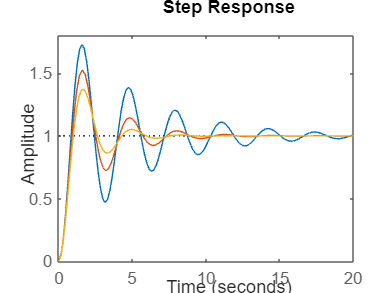


% come si può vedere è aumentato il tempo di risalita(di poco) e il tempo
% di picco è anche leggermente aumentato, mentre il tempo di assestamento è
% diminuito
% abbiamo allontanato i poli dall'asse immaginaria( la parte immaginaria è
% diminuita e la parte reale è aumentata).
delta3 = 0.3;
omegan = 2;
n = omegan^2; %numeratore
d = [1 2*delta3*omegan omegan^2]; %denominatore
G3 = tf(n,d);
roots(d);
step(G3,20); hold off;

disp("G3")

G3


disp(stepinfo(G3));

         RiseTime: 0.6618
    TransientTime: 5.6151
     SettlingTime: 5.6151
      SettlingMin: 0.8614
      SettlingMax: 1.3714
        Overshoot: 37.1410
       Undershoot: 0
             Peak: 1.3714
         PeakTime: 1.6118



% vario wn e lascio costante delta
delta = 0.1;
omegan4 = 1;
n = omegan4^2; %numeratore
d = [1 2*delta*omegan4 omegan4^2]; %denominatore
G4 = tf(n,d);
roots(d);
figure(2);
step(G4,20); hold on;
stepinfo(G4);
disp("G4");

G4


disp(stepinfo(G4));

         RiseTime: 1.1272
    TransientTime: 38.3730
     SettlingTime: 38.3730
      SettlingMin: 0.4685
      SettlingMax: 1.7292
        Overshoot: 72.9156
       Undershoot: 0
             Peak: 1.7292
         PeakTime: 3.1416




delta = 0.1;
omegan5 = 2;
n = omegan5^2; %numeratore
d = [1 2*delta*omegan5 omegan5^2]; %denominatore
G5 = tf(n,d);
roots(d);
step(G5,20);hold on;
stepinfo(G5);
disp("G5");

G5


disp(stepinfo(G5));

         RiseTime: 0.5636
    TransientTime: 19.1865
     SettlingTime: 19.1865
      SettlingMin: 0.4685
      SettlingMax: 1.7292
        Overshoot: 72.9156
       Undershoot: 0
             Peak: 1.7292
         PeakTime: 1.5708



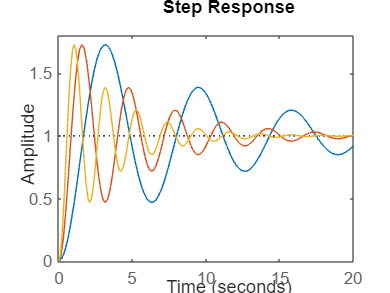

delta = 0.1;
omegan6 = 3;
n = omegan6^2; %numeratore
d = [1 2*delta*omegan6 omegan6^2]; %denominatore
G6 = tf(n,d);
roots(d);
step(G6,20);hold on;

stepinfo(G6);
disp("G6");

G6


disp(stepinfo(G6));

         RiseTime: 0.3757
    TransientTime: 12.7910
     SettlingTime: 12.7910
      SettlingMin: 0.4685
      SettlingMax: 1.7292
        Overshoot: 72.9156
       Undershoot: 0
             Peak: 1.7292
         PeakTime: 1.0472

